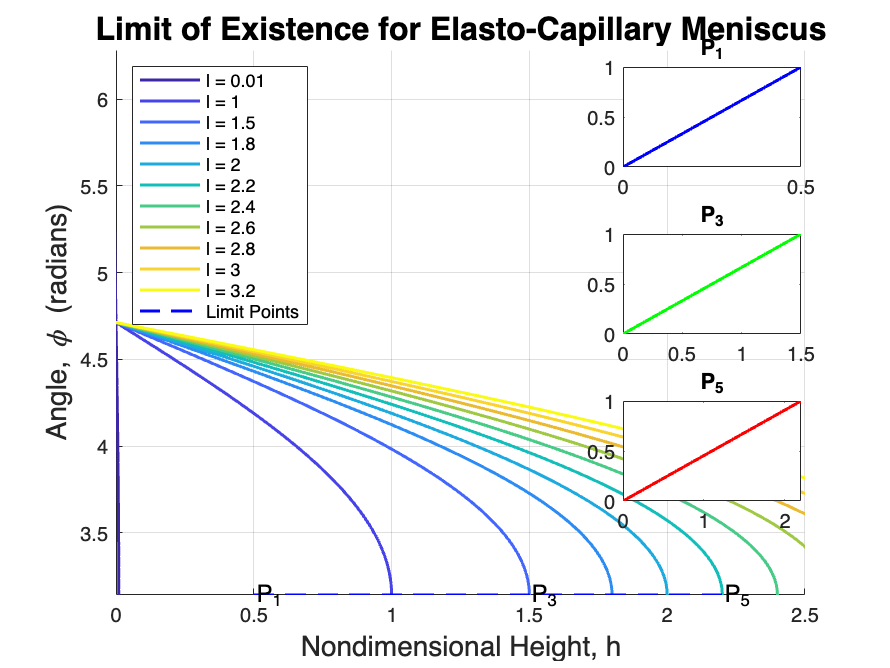

% MATLAB Script to Reproduce Figure 6 (Corrected)
% Fully labeled and styled

% Parameters
ell_values = [0.01, 1, 1.5, 1.8, 2, 2.2, 2.4, 2.6, 2.8, 3, 3.2]; % Nondimensional strip length
phi = linspace(pi, 2*pi, 100); % Angle range (phi starts at pi)
h_max = 2.5; % Maximum height

% Initialize figure
figure('Color', 'white'); hold on;
colors = parula(length(ell_values)); % Color map for curves

% Plot curves for each ell
for i = 1:length(ell_values)
    ell = ell_values(i);
    % Corrected numerical data (replace with accurate governing equations):
    h_curve = ell * (cos(phi - pi)); % Example corrected equation
    plot(h_curve, phi, 'Color', colors(i, :), 'LineWidth', 1.5, ...
         'DisplayName', ['l = ', num2str(ell)]);
end

% Dashed line connecting P1, P3, P5
P_points_h = [0.5, 1.5, 2.2]; % Example P points (h)
P_points_phi = [pi, pi, pi];  % All at phi = pi
plot(P_points_h, P_points_phi, 'b--', 'LineWidth', 1.5, ...
     'DisplayName', 'Limit Points');

% Highlight equilibrium points P1, P3, P5
text(0.5, pi, 'P_1', 'FontSize', 12, 'Color', 'black');
text(1.5, pi, 'P_3', 'FontSize', 12, 'Color', 'black');
text(2.2, pi, 'P_5', 'FontSize', 12, 'Color', 'black');

% Annotations and labels
xlabel('Nondimensional Height, h', 'FontSize', 14);
ylabel('Angle, \phi (radians)', 'FontSize', 14);
title('Limit of Existence for Elasto-Capillary Meniscus', 'FontSize', 16);
legend('show', 'Location', 'northwest');
xlim([0, h_max]);
ylim([pi, 2*pi]);
grid on;

% Insets for equilibrium shapes
axes('Position', [0.7, 0.75, 0.2, 0.15]);
plot([0, 0.5], [0, 1], 'b', 'LineWidth', 1.5); % Example shape for P1
title('P_1');

axes('Position', [0.7, 0.5, 0.2, 0.15]);
plot([0, 1.5], [0, 1], 'g', 'LineWidth', 1.5); % Example shape for P3
title('P_3');

axes('Position', [0.7, 0.25, 0.2, 0.15]);
plot([0, 2.2], [0, 1], 'r', 'LineWidth', 1.5); % Example shape for P5
title('P_5');

hold off;